# 01 波形の切り出しについて

 　波形の切り出しに関して以下の三種類の検証を行った。

- 波形のピークを用いた切り出し

- ノイズ信号に対するガイド波形を用いた波形の切り出し

- 時間軸方向の歪に対する（ジッタ）波形の切り出し

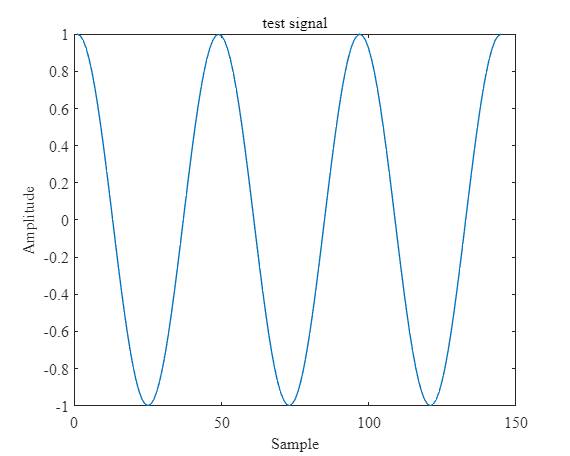

%% test 波形の作成
%パラメータ
Fs = 48e3;
f = 1000;
T = 1/f * 3;
t = 0:1/Fs:T;
vis = Visual(Fs,f);

%余弦波の作成
signal = cos(2*pi*f*t);

vis.plotSignal(signal);
title("test signal")

%% Object を宣言
pul = Separation(Fs,f,signal,1);
pus = Separation(Fs,f,signal,2);

## 1. 波形のピークを用いた切り出し

    波形のピークを求めて切り出し点を決める。簡単にいうとピークピッキングを隣接サンプル間の差分から求めている。

   　-  Sepration.separateMotionを使用

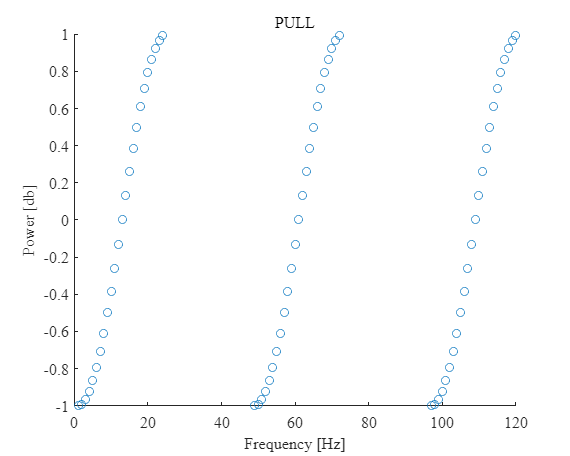

% PULL の分離
pull_signal = pul.separateMotion;
vis.plotEachSignal(pull_signal,"PULL");

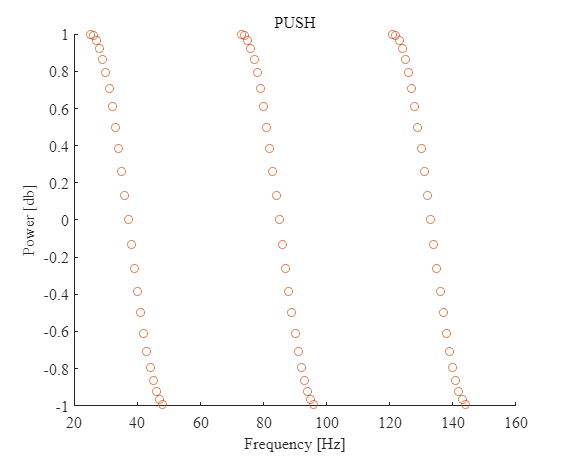

% PUSH の分離
push_signal = pus.separateMotion;
vis.plotEachSignal(push_signal,"PUSH");